# Pb4

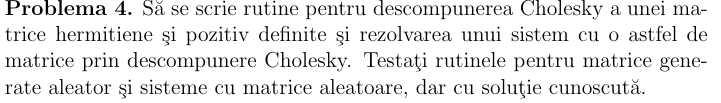

## Descompunerea Cholesky

function R = cholesky_decomp(A)
% INPUT:
%   A - matricea simetrica si pozitiv definita (n x n)
%
% OUTPUT:
%   R - matricea triunghiulara superiora astfel incat A = R' * R
%
% Metoda: Descompunere Cholesky (Algoritmul 4 din curs)
% Transforma A in R, lucrand direct pe submatricea de sus

    R = A;              % R := A
    m = size(A, 1);     % dimensiunea matricei

    for k = 1:m
        % -------------------------
        % R(k, k:m) := R(k, k:m) / sqrt(R(k, k))
        R(k, k:m) = R(k, k:m) / sqrt(R(k, k));  % normalizare pe linia k

        % -------------------------
        % pentru fiecare j = k+1 .. m
        for j = k+1:m
            % R(j, j:m) := R(j, j:m) - R(k, j:m) * R(k, j) / R(k, k)
            % echivalent cu eliminare a contributiei liniei k asupra liniei j
            R(j, j:m) = R(j, j:m) - (R(k, j:m) * R(k, j)) / R(k, k);
        end
    end
end


function x = rezolva_cholesky(A, b)
% INPUT:
%   A - matrice simetrica si pozitiv definita (n x n)
%   b - vectorul termenilor liberi (n x 1)
%
% OUTPUT:
%   x - solutia sistemului Ax = b
%
% Metoda: Se face Cholesky A = R' * R, apoi:
%   1. Se rezolva R' * y = b (substitutie directa)
%   2. Se rezolva R * x = y  (substitutie inversa)

    R = cholesky_decomp(A);  % Descompunerea A = R' * R
    n = length(b);
    y = zeros(n, 1);
    x = zeros(n, 1);

    % Substitutie directa: R' * y = b
    for i = 1:n
        y(i) = (b(i) - R(1:i-1, i)' * y(1:i-1)) / R(i, i);
    end

    % Substitutie inversa: R * x = y
    for i = n:-1:1
        x(i) = (y(i) - R(i, i+1:n) * x(i+1:n)) / R(i, i);
    end
end

n = 5;
B = randn(n);
A = B' * B;             % A este simetrica si pozitiv definita
x_exact = ones(n,1);    % solutie cunoscuta
b = A * x_exact;

x = rezolva_cholesky(A, b);

% Afisare rezultate
disp('Solutie obtinuta:');

Solutie obtinuta:


disp(x);

   1.240734832153316
   0.990820915534344
   1.206584608664697
   0.601632401758827
   0.390747246014766




fprintf("||x - x_exact|| = %.3e\n", norm(x - x_exact));

||x - x_exact|| = 7.941e-01


fprintf("||Ax - b||      = %.3e\n", norm(A * x - b));

||Ax - b||      = 7.753e-01
